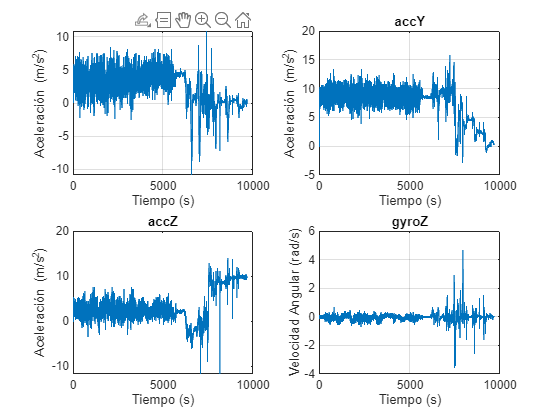

% Leer el archivo JSON con datos de aceleración y giroscopio 
file_path = 'KartsGustavo.json'; % Reemplaza con la ruta real del archivo
json_data = jsondecode(fileread(file_path));

% Extraer nombres de sensores y valores
sensors = {json_data.payload.sensors.name}; % Nombres de los sensores
values = json_data.payload.values; % Valores de las mediciones
values_matrix = vertcat(values);

% Crear tabla para facilitar el manejo
data_table = array2table(values_matrix, 'VariableNames', sensors);

% Asignar variables individuales
accX = data_table.accX; % Aceleración en X (m/s^2)
accY = data_table.accY; % Aceleración en Y (m/s^2)
accZ = data_table.accZ; % Aceleración en Z (m/s^2)
gyroZ = deg2rad(data_table.gyroZ); % Velocidad angular en Z (°/s)

% Verificar si las aceleraciones están en 'g' y convertirlas a m/s^2
if max(abs(accX)) < 5 && max(abs(accY)) < 5 % Suposición de valores en 'g'
    accX = accX * 9.81;
    accY = accY * 9.81;
end

% Gráficas inciales de datos en bruto
subplot(2,2,1);
plot(accX);
xlabel('Tiempo (s)');
ylabel('Aceleración (m/s^2)');
title('accX');
grid on;
subplot(2,2,2);
plot(accY);
xlabel('Tiempo (s)');
ylabel('Aceleración (m/s^2)');
title('accY');
grid on;
subplot(2,2,3);
plot(accZ);
xlabel('Tiempo (s)');
ylabel('Aceleración (m/s^2)');
title('accZ');
subplot(2,2,4);
plot(gyroZ);
xlabel('Tiempo (s)');
ylabel('Velocidad Angular (rad/s)');
title('gyroZ');
grid on;

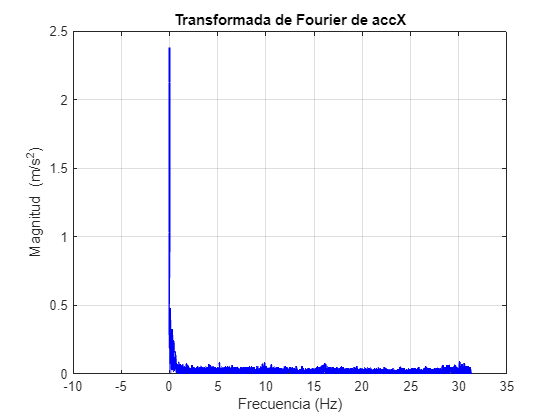


% Definir parámetros de la señal
fs = 62.5; % Frecuencia de muestreo (Hz)
dt = 1 / fs; % Intervalo de tiempo (s)

% Calcular la Transformada de Fourier
N = length(accX); % Número de puntos
fft_signal = fft(accX); % Transformada de Fourier
P2 = abs(fft_signal / N); % Magnitud de la transformada (doble cara)
P1 = P2(1:floor(N/2)+1); % Magnitud de la transformada (cara única)
P1(2:end-1) = 2 * P1(2:end-1); % Ajustar magnitudes para cara única

% Eje de frecuencias
f = fs * (0:(N/2)) / N;

% Graficar la FFT
figure;
plot(f, P1, 'b', 'LineWidth', 1.5);
title('Transformada de Fourier de accX');
xlabel('Frecuencia (Hz)');
ylabel('Magnitud (m/s^2)');
grid on;
xlim([-10 35])

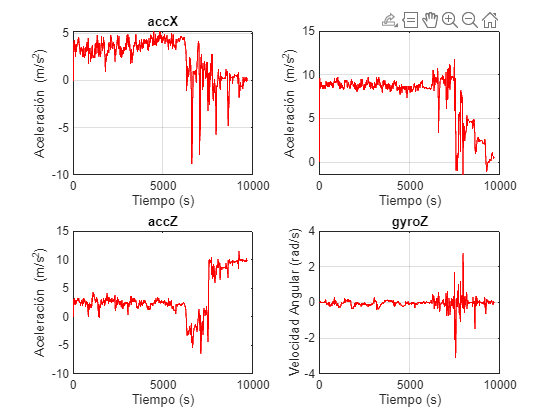


% Aplicar filtro a las aceleraciones
fc = 2; % Frecuencia de corte en Hz
[b, a] = butter(4, 2 * fc / fs, 'low');
accX_f = filter(b, a, accX);
accY_f = filter(b, a, accY);
accZ_f = filter(b, a, accZ);
gyroZ_f = filter(b, a, gyroZ);

% Gráficas con datos filtrados
figure;
subplot(2,2,1);
plot(accX_f, 'r');
xlabel('Tiempo (s)');
ylabel('Aceleración (m/s^2)');
title('accX');
grid on;
subplot(2,2,2);
plot(accY_f, 'r');
xlabel('Tiempo (s)');
ylabel('Aceleración (m/s^2)');
title('accY');
grid on;
subplot(2,2,3);
plot(accZ_f, 'r');
xlabel('Tiempo (s)');
ylabel('Aceleración (m/s^2)');
title('accZ');
subplot(2,2,4);
plot(gyroZ_f, 'r');
xlabel('Tiempo (s)');
ylabel('Velocidad Angular (rad/s)');
title('gyroZ');
grid on;

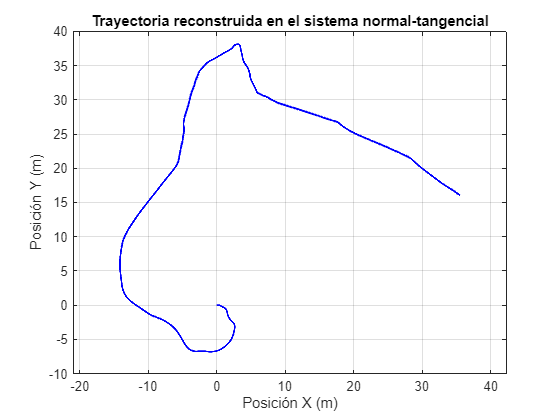


% Inicializar variables
N_samples = length(accX_f);
v = zeros(1, N_samples); % Magnitud de la velocidad
x = zeros(1, N_samples); % Posición en X
y = zeros(1, N_samples); % Posición en Y
at = zeros(1, N_samples); % Aceleración tangencial
an = zeros(1, N_samples); % Aceleración normal
theta = zeros(1, N_samples); % Orientación del kart

% Reconstrucción en sistema normal-tangencial
for i = 2:N_samples
    % Magnitud de la velocidad
    v(i) = v(i-1) + (sqrt(accX_f(i)^2 + accY_f(i)^2))/1000 * dt;

    % Aceleraciones tangencial y normal
    at(i) = ((accX_f(i) * cos(theta(i-1)) + accY_f(i) * sin(theta(i-1)))); % Proyección tangencial
    an(i) = ((accX_f(i) * sin(theta(i-1)) - accY_f(i) * cos(theta(i-1)))); % Proyección normal

    % Actualizar orientación
    theta(i) = theta(i-1) + gyroZ_f(i-1) * dt; % θ acumulativo

    % Calcular desplazamientos en el sistema global
    dx = v(i) * cos(theta(i)) * dt;
    dy = v(i) * sin(theta(i)) * dt;
    x(i) = x(i-1) + dx;
    y(i) = y(i-1) + dy;
end

% Graficar la trayectoria reconstruida
figure;
plot(x, y, 'b', 'LineWidth', 1.5);
title('Trayectoria reconstruida en el sistema normal-tangencial');
xlabel('Posición X (m)');
ylabel('Posición Y (m)');
grid on;
axis equal;
ylim([-10 40])

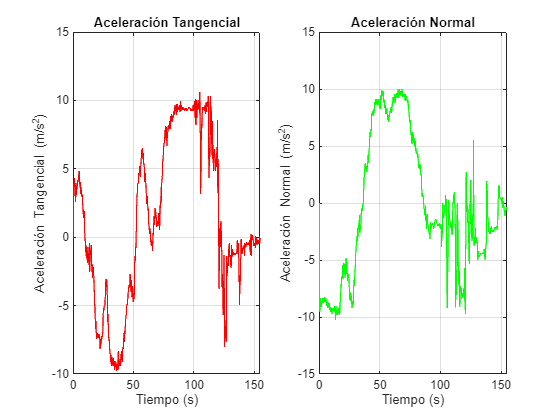


% Graficar aceleración tangencial, normal, velocidades angulares y lineales
figure;
subplot(1, 2, 1);
plot((1:N_samples) * dt, at, 'r');
title('Aceleración Tangencial');
xlabel('Tiempo (s)');
ylabel('Aceleración Tangencial (m/s^2)');
grid on;

subplot(1, 2, 2);
plot((1:N_samples) * dt, an, 'g');
title('Aceleración Normal');
xlabel('Tiempo (s)');
ylabel('Aceleración Normal (m/s^2)');
grid on;

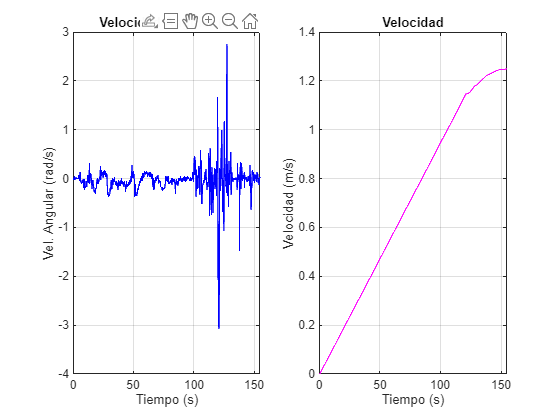


figure;
subplot(1, 2, 1);
plot((1:N_samples) * dt, gyroZ_f, 'b');
title('Velocidad Angular (Z)');
xlabel('Tiempo (s)');
ylabel('Vel. Angular (rad/s)');
grid on;

subplot(1, 2, 2);
plot((1:N_samples) * dt, v, 'm');
title('Velocidad');
xlabel('Tiempo (s)');
ylabel('Velocidad (m/s)');
grid on;